clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459

data.CzasLokalnyUTC0000(1:4)

ans = 4×1 datetime array
   NaT                
   15/03/2024 11:00:09
   15/03/2024 11:00:14
   15/03/2024 11:00:19


data.CzasLokalnyUTC0000(n-3:n)

ans = 4×1 datetime array
   16/04/2024 08:49:27
   16/04/2024 08:49:32
   16/04/2024 08:49:37
   NaT                


From time vector:

T=5; %[s]
fs=1/T; %[Hz]
t=T*(1:n-1);
Wlot=0.1*data.Wlot;
X=Wlot;
compressor=data.Kompresor1;
[x,nan_indices]  = GetRidOfNans(X);
day=24*60*60*fs

day = 17280

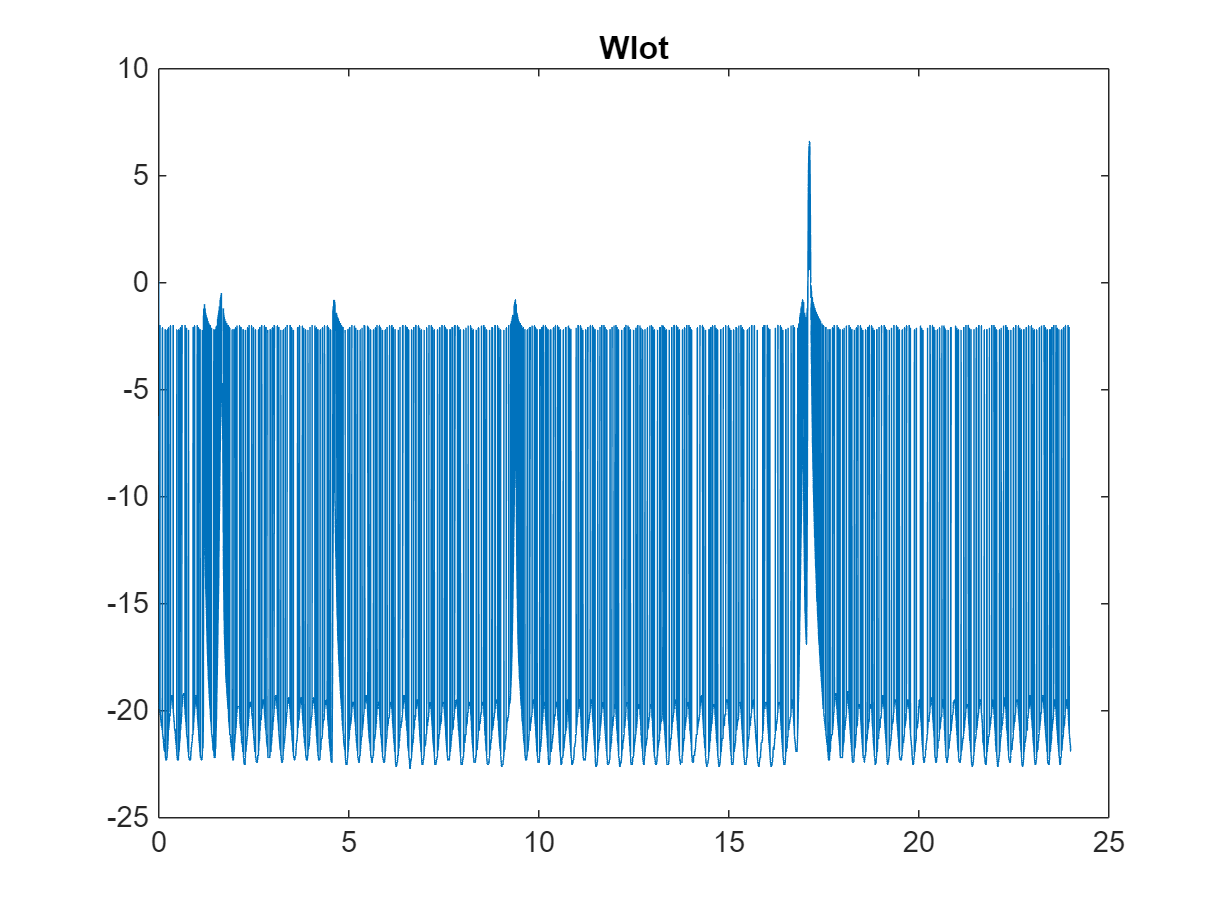

t_day=T*(1:day);
x_day=x(1:day);
compressor_day=compressor(1:day);
plot(t_day/(60*60),x_day)
title('Wlot')

## Interpolation

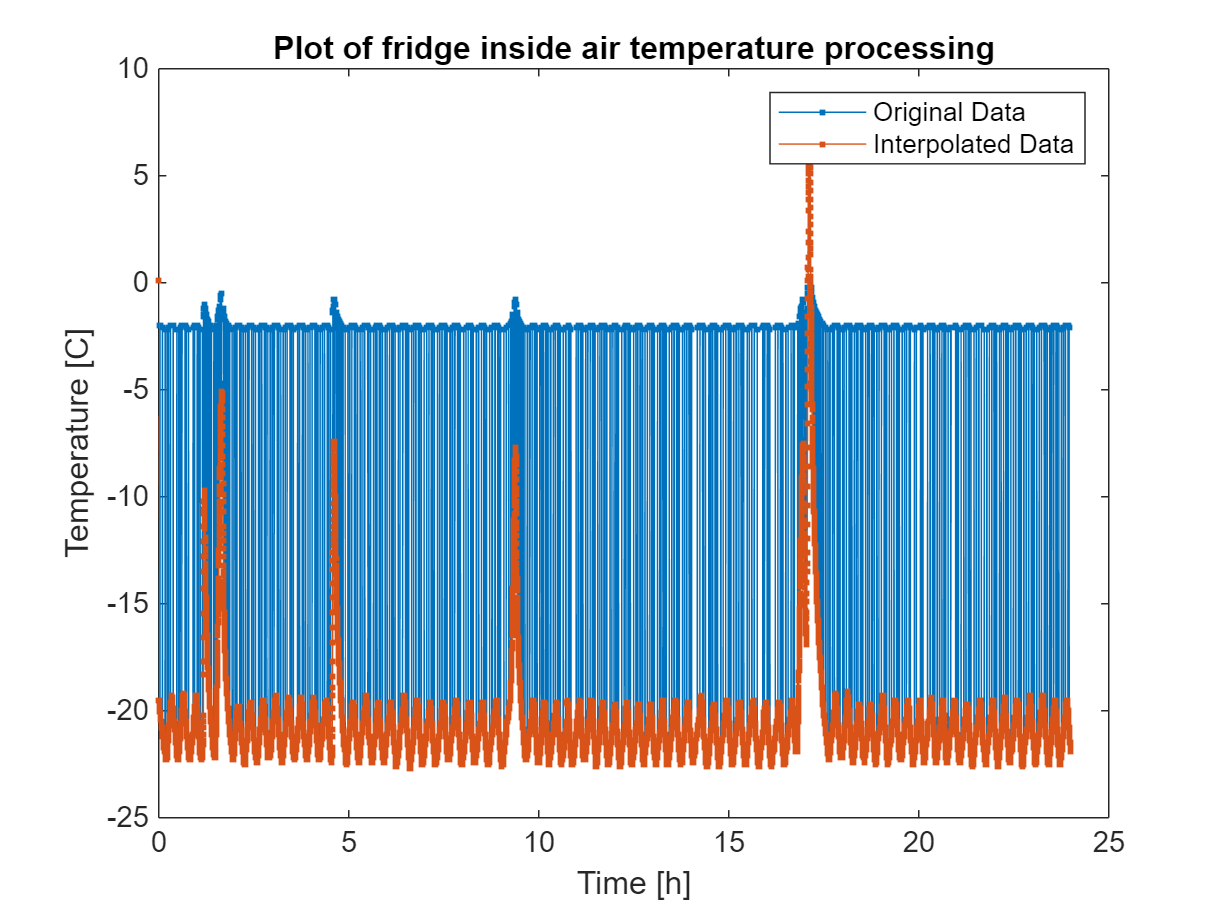

x_day_interp = InterpolateData(x_day,[-5,0],t_day);
% Plot original and interpolated data
plot(t_day/(60*60),x_day, '.-', 'DisplayName', 'Original Data');
hold on;
plot(t_day/(60*60),x_day_interp, '.-', 'DisplayName', 'Interpolated Data');hold off
title('Plot of fridge inside air temperature processing')
xlabel('Time [h]');
ylabel('Temperature [C]')
% xlim([6.5,8.5])
legend;

## Remooving anomalies

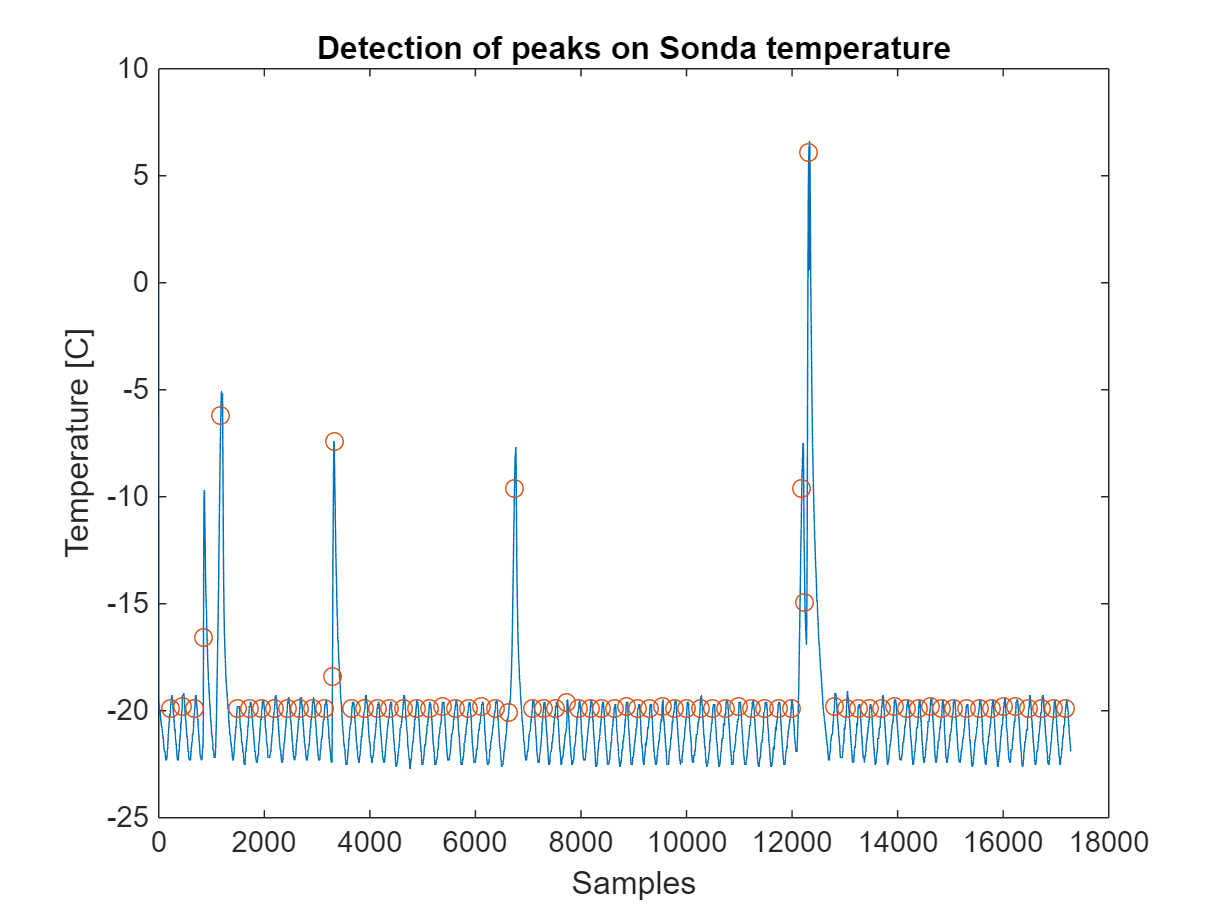

anomaly_locs=compressorCycles(compressor_day);
features = FeatureExtract(x_day_interp,anomaly_locs);
plot(x_day_interp);hold on
plot(anomaly_locs,(x_day_interp(anomaly_locs)),'o');hold off
title('Detection of peaks on Sonda temperature')
xlabel('Samples')
ylabel('Temperature [C]')

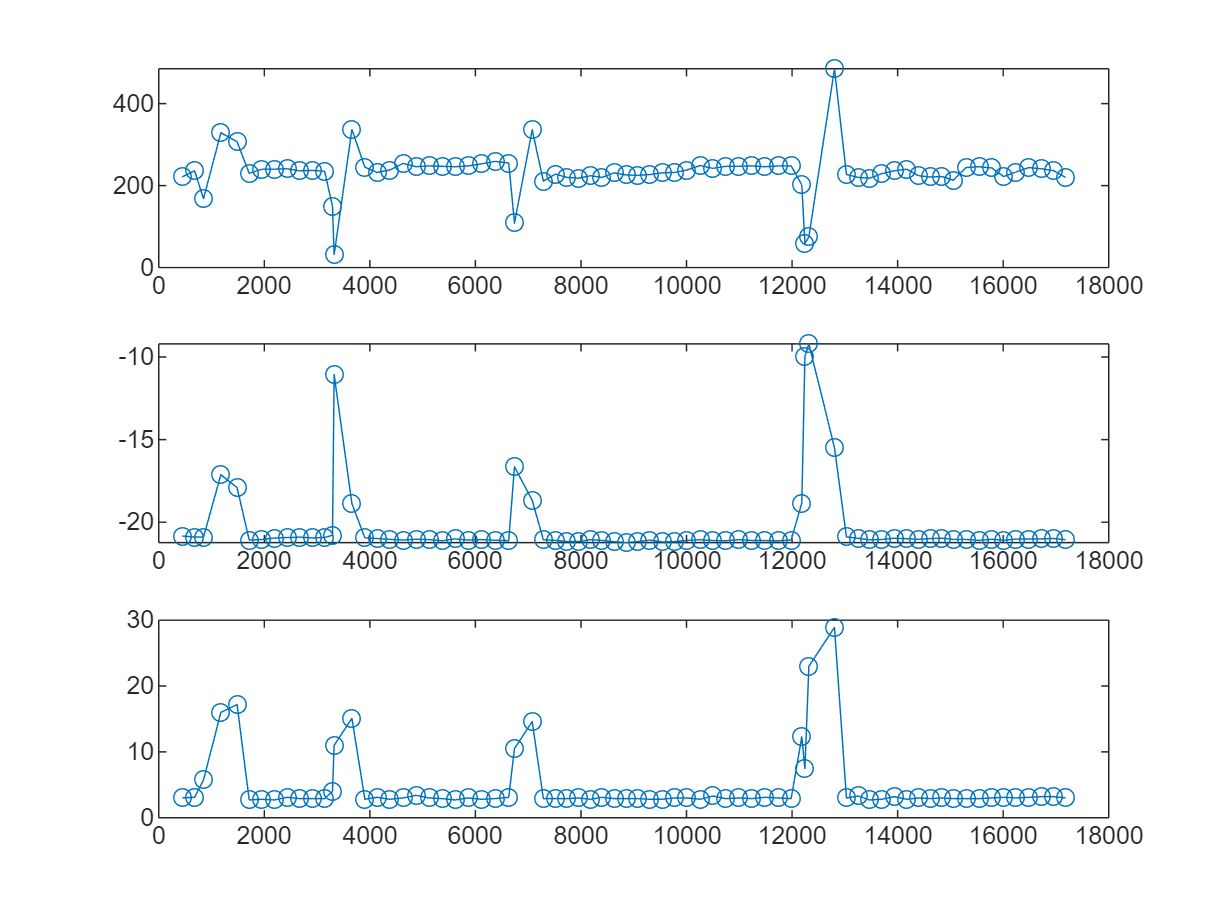

f1=zeros(1,length(anomaly_locs)-1);
for i=1:length(anomaly_locs)-1
    f1(i)=anomaly_locs(i+1)-anomaly_locs(i);
end
anomaly_locs=anomaly_locs(2:end);
figure 
subplot(311)
plot(anomaly_locs,f1,'o-')
subplot(312)
plot(anomaly_locs,features(3,:),'o-')
subplot(313)
plot(anomaly_locs,features(1,:)-features(2,:),'o-')

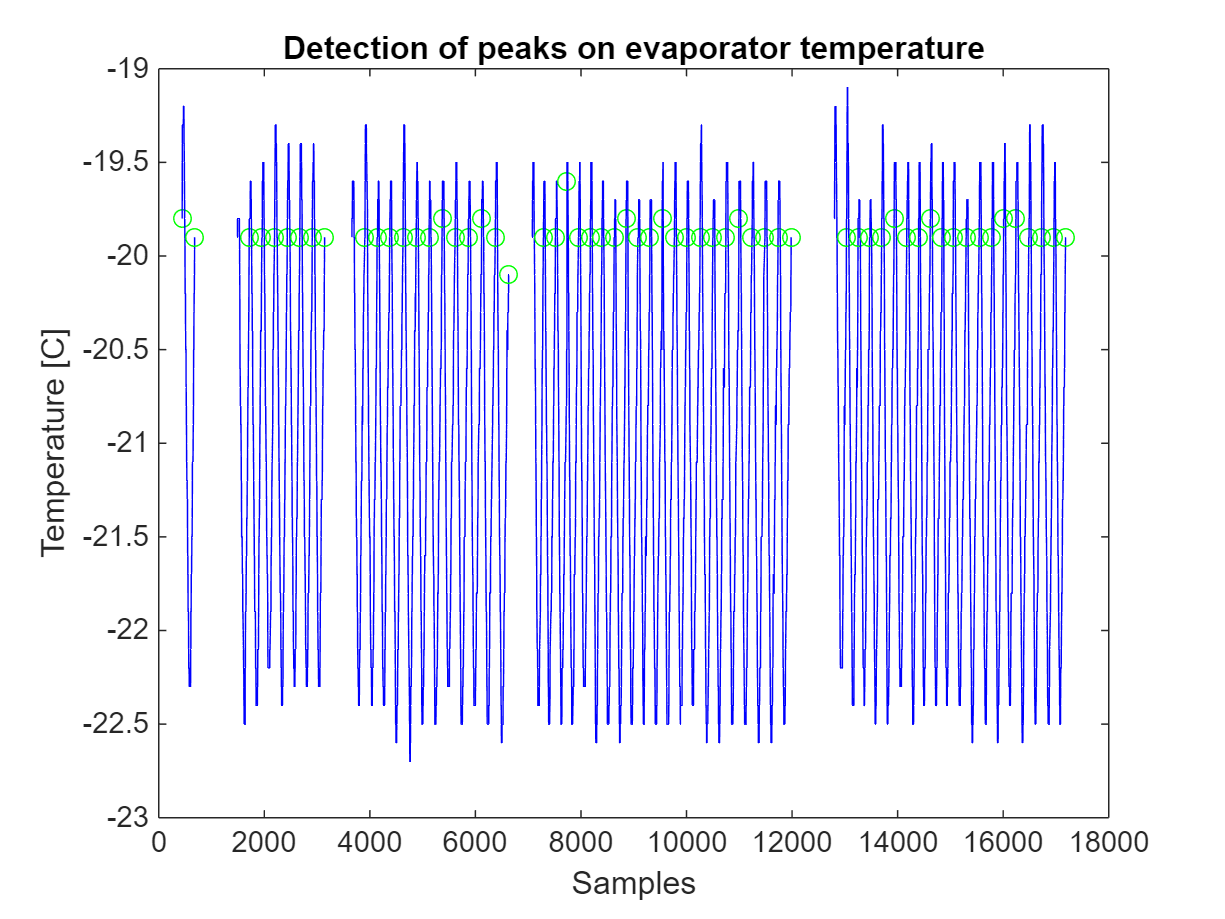

fridge_air_temp_p2p=features(1,:)-features(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(fridge_air_temp_p2p);
plot(anomaly_locs(1),(x_day_interp(anomaly_locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(features)
    
    if (TF(i)==0)
        plot(anomaly_locs(i-1):anomaly_locs(i),...
            (x_day_interp(anomaly_locs(i-1):anomaly_locs(i))),"Color",'blue');
        plot(anomaly_locs(i),(x_day_interp(anomaly_locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},anomaly_locs(i-1):anomaly_locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

### Setting proper index containee:

set=1;
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60*60*2*fs
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

## Peak-Valleys detection based compressor prediction:

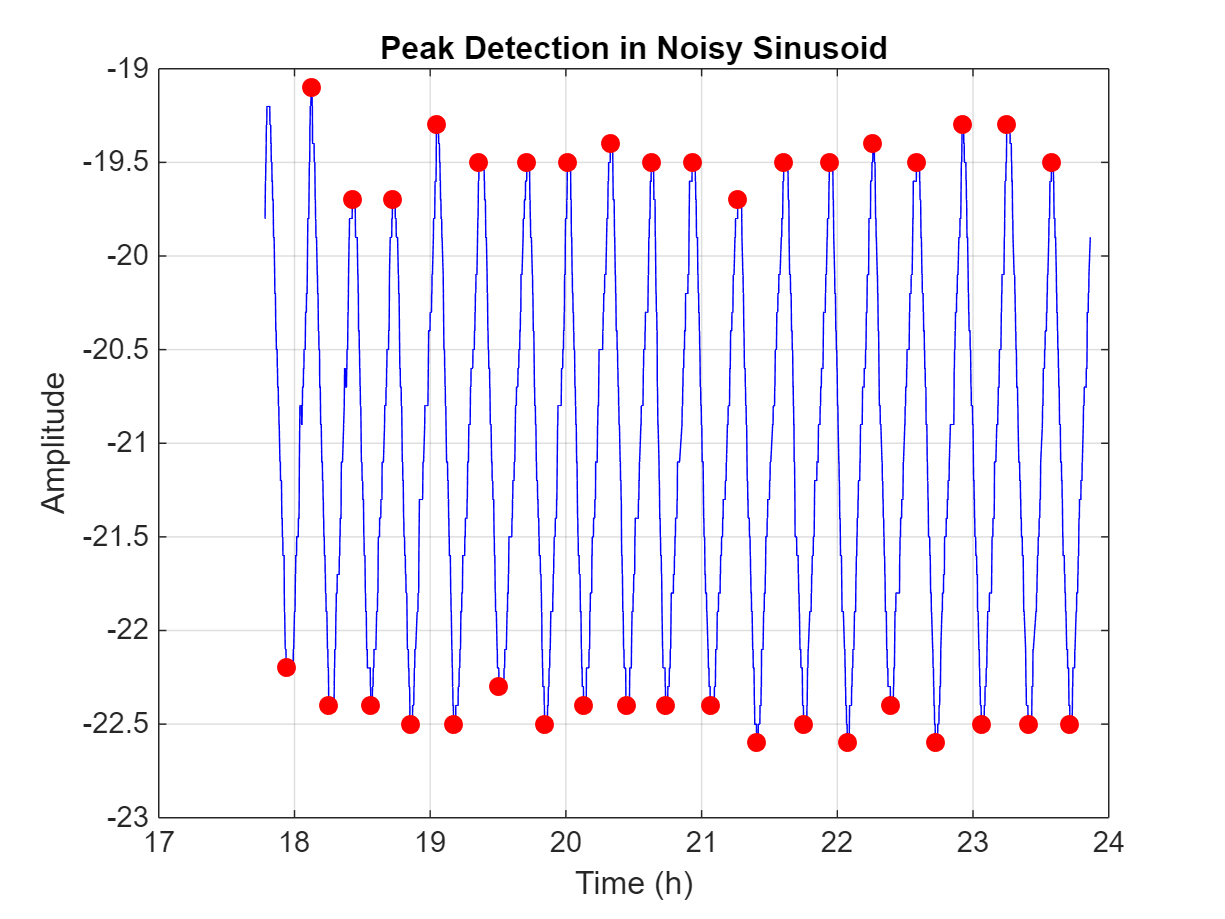

% % Find peaks
% [pks, locs_peaks] = findpeaks(x_day_interp(usableDataIndex{4}), ...
%     'MinPeakProminence', 0.8, ...   % Ignore small peaks (noise)
%     'MinPeakDistance', 0.17);        % Enforce minimum spacing (seconds)
% % Find valleys
% [valleys, locs_valleys] = findpeaks(-x_day_interp(usableDataIndex{4}), ...
%     'MinPeakProminence', 0.8, ...   % Ignore small peaks (noise)
%     'MinPeakDistance', 0.17);        % Enforce minimum spacing (seconds)
% valleys=-valleys;
[pks, locs_peaks, valleys, locs_valleys] = findPeaksAndValleys( x_day_interp(usableDataIndex{4}), ...
                                  'MinPeakProminence', 0.8, ...
                                  'MinPeakDistance',   0.17 );
% Plot results
figure;
t_indexed=t_day(usableDataIndex{4});
plot(t_day(usableDataIndex{4})/(60*60),x_day_interp(usableDataIndex{4}), 'b'); hold on;
plot(t_indexed(locs_peaks)/(60*60), pks, 'ro', 'MarkerFaceColor', 'r');
plot(t_indexed(locs_valleys)/(60*60), valleys, 'ro', 'MarkerFaceColor', 'r');

xlabel('Time (h)');
ylabel('Amplitude');
title('Peak Detection in Noisy Sinusoid');
grid on; hold off

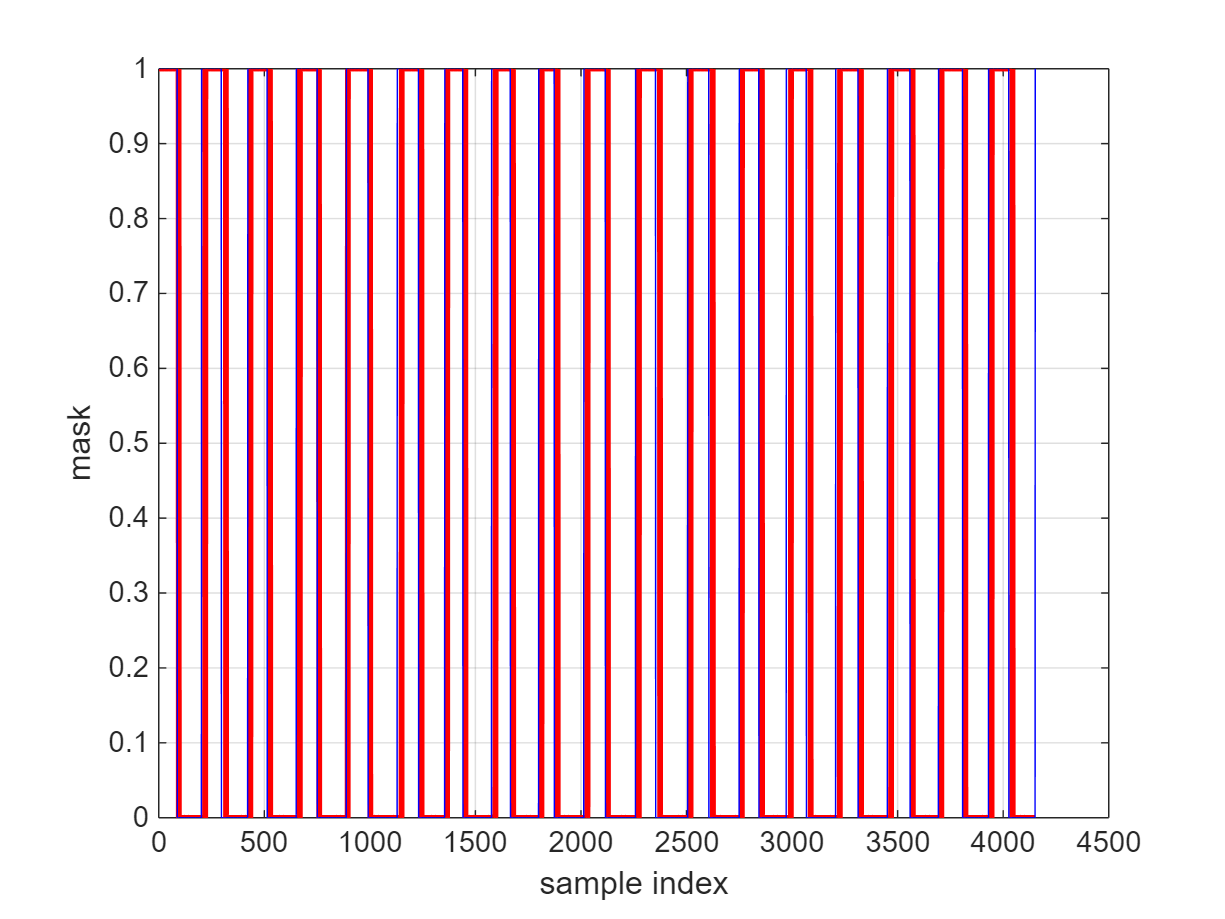

N=length(usableDataIndex{4});

mask = peakValleyMask(locs_peaks,locs_valleys,N);
compressor_indexed=compressor_day(usableDataIndex{4});
% plot to check
t = 1:N;
plot(mask(locs_peaks(1):end),'-','LineWidth',2,'Color','r');hold on
plot(compressor_indexed(locs_peaks(1):end), 'b'); hold off;
grid on
xlabel 'sample index', ylabel 'mask'

mask_pred=mask(locs_peaks(1):end);
mask_meas=compressor_indexed(locs_peaks(1):end)';
mask_meas=mask_meas(1:length(mask_pred));
% compare
stats = compareOnTime(mask_pred, mask_meas);

% display
fprintf('Measured ON‐time = %.1f h\n', stats.timeOnMeas/3600);

Measured ON‐time = 0.5 h


fprintf('Predicted ON‐time= %.1f h\n', stats.timeOnPred/3600);

Predicted ON‐time= 0.5 h


fprintf('Difference      = %+0.1f s  (%.1f%%)\n',...
        stats.diffTime, stats.pctError);

Difference      = -10.0 s  (-0.6%)


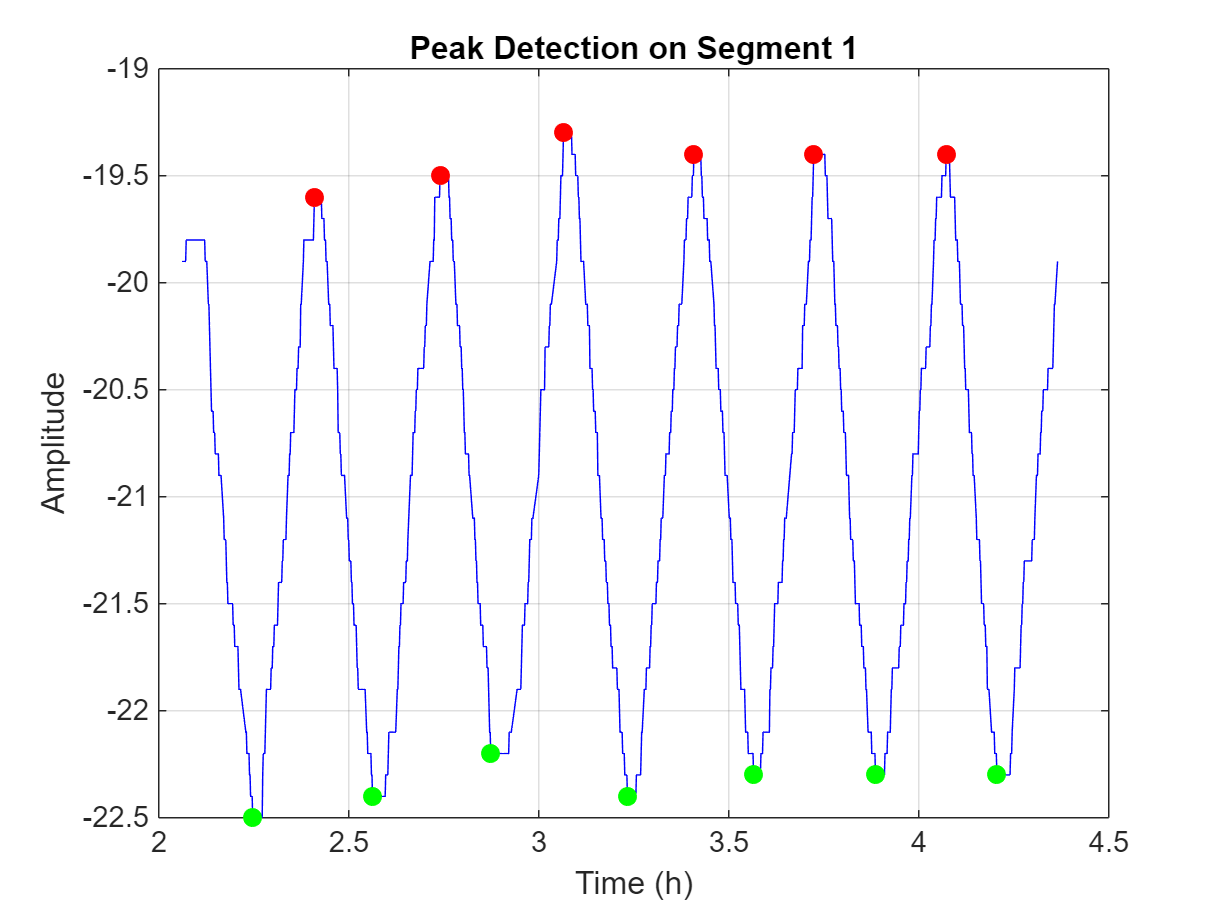

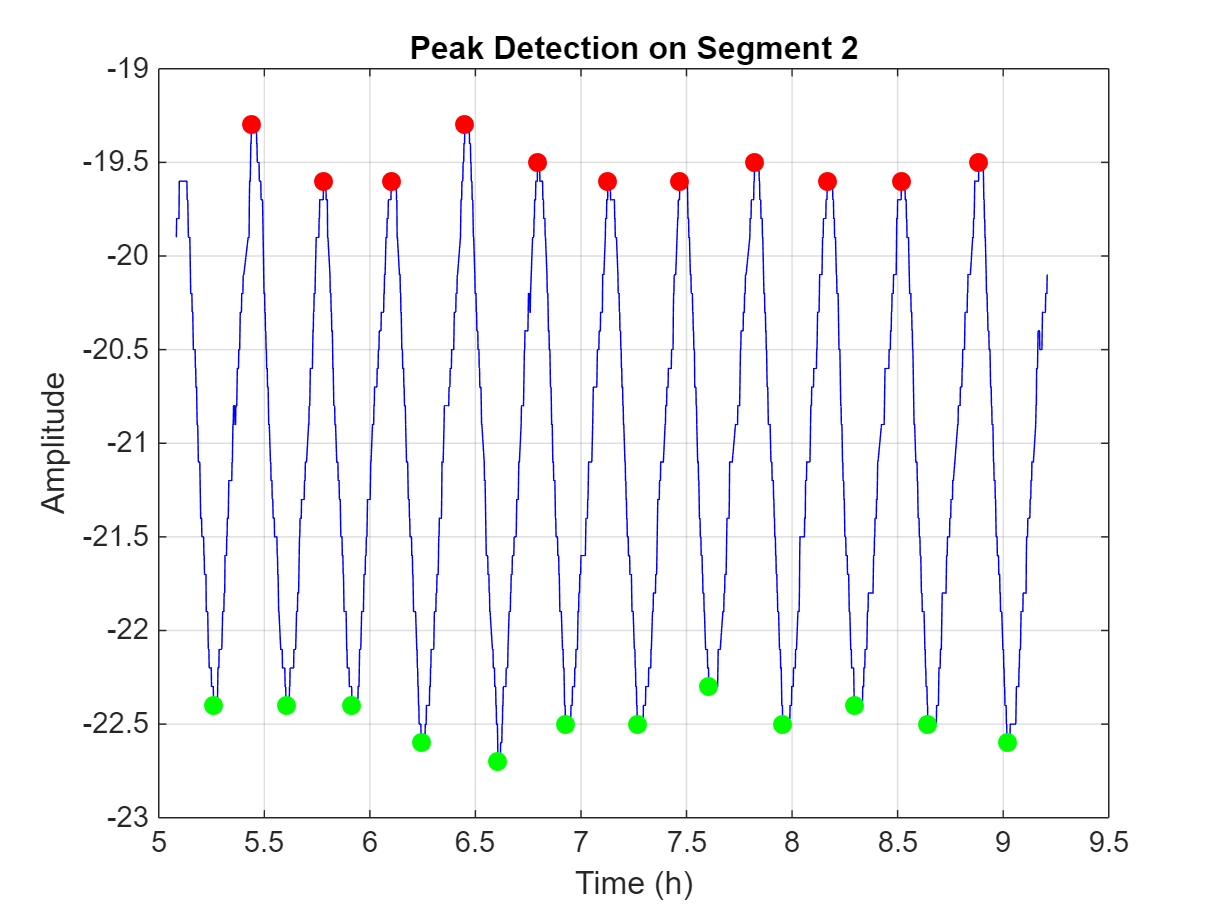

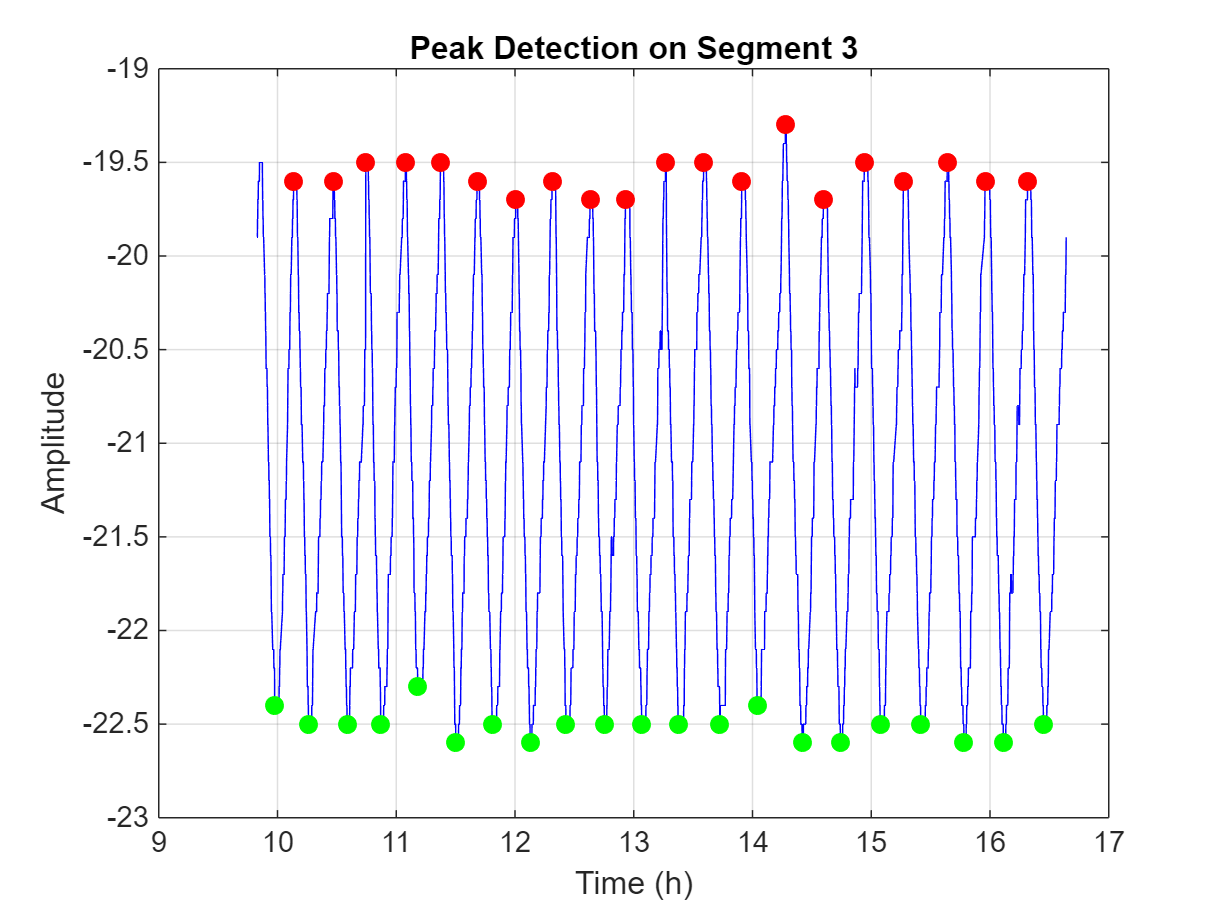

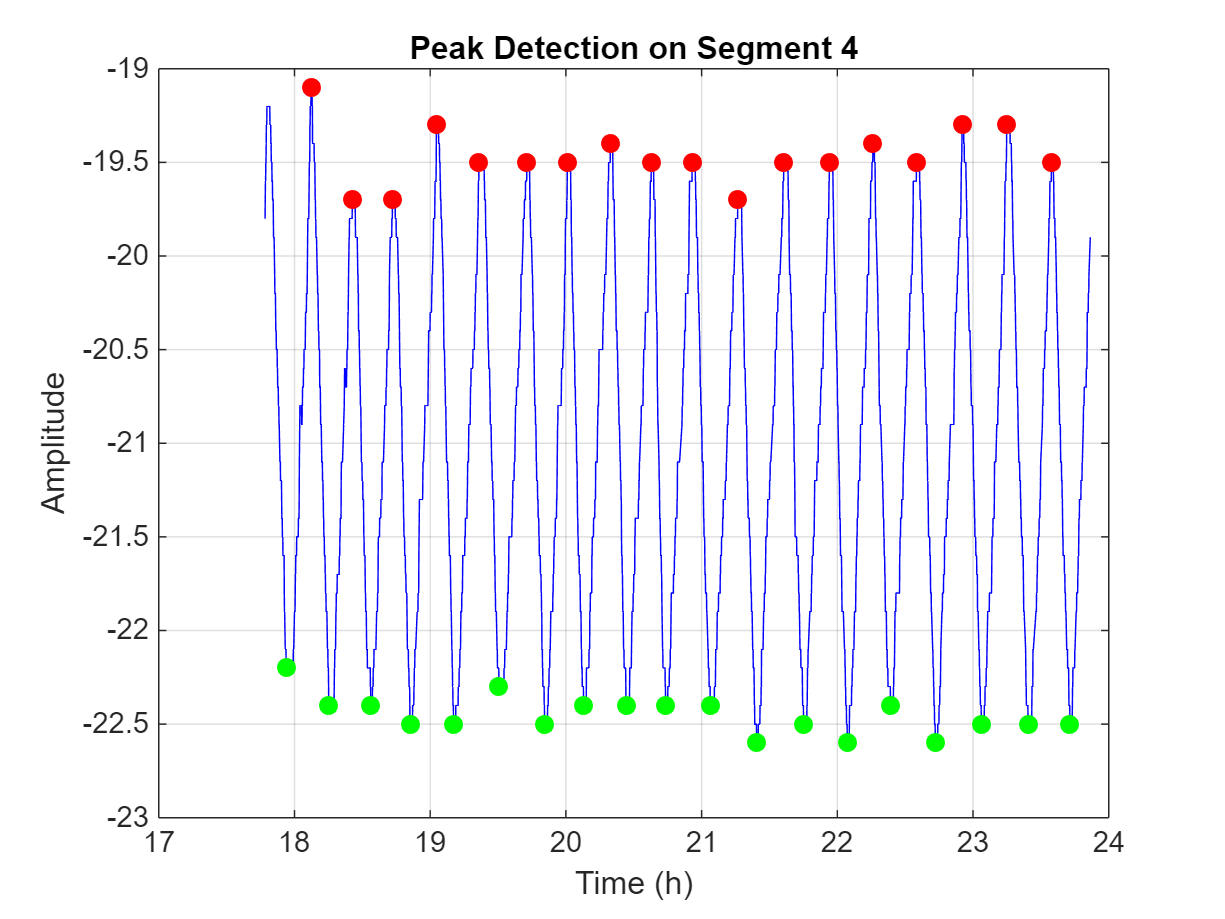

nSets = numel(usableDataIndex);

pks        = cell(nSets,1);
locs_peaks = cell(nSets,1);
valleys    = cell(nSets,1);
locs_valleys  = cell(nSets,1);

for i = 1:nSets
    idx = usableDataIndex{i};

    % run your peak/valley finder
    [pks{i}, locs_peaks{i}, valleys{i}, locs_valleys{i}] = ...
        findPeaksAndValleys( x_day_interp(idx), ...
                             'MinPeakProminence', 0.8, ...
                             'MinPeakDistance',   0.17 );

    % extract time & amplitude for this chunk
    t_chunk = t_day(idx);
    x_chunk = x_day_interp(idx);

    % plot into its own figure
    figure
    plot(t_chunk/(3600), x_chunk,       'b-'); hold on
    plot(t_chunk(locs_peaks{i})/(3600), pks{i},    'ro', 'MarkerFaceColor','r');
    plot(t_chunk(locs_valleys{i})/(3600),  valleys{i},'go', 'MarkerFaceColor','g');
    hold off
    grid on
    xlabel('Time (h)')
    ylabel('Amplitude')
    title(sprintf('Peak Detection on Segment %d', i))
end

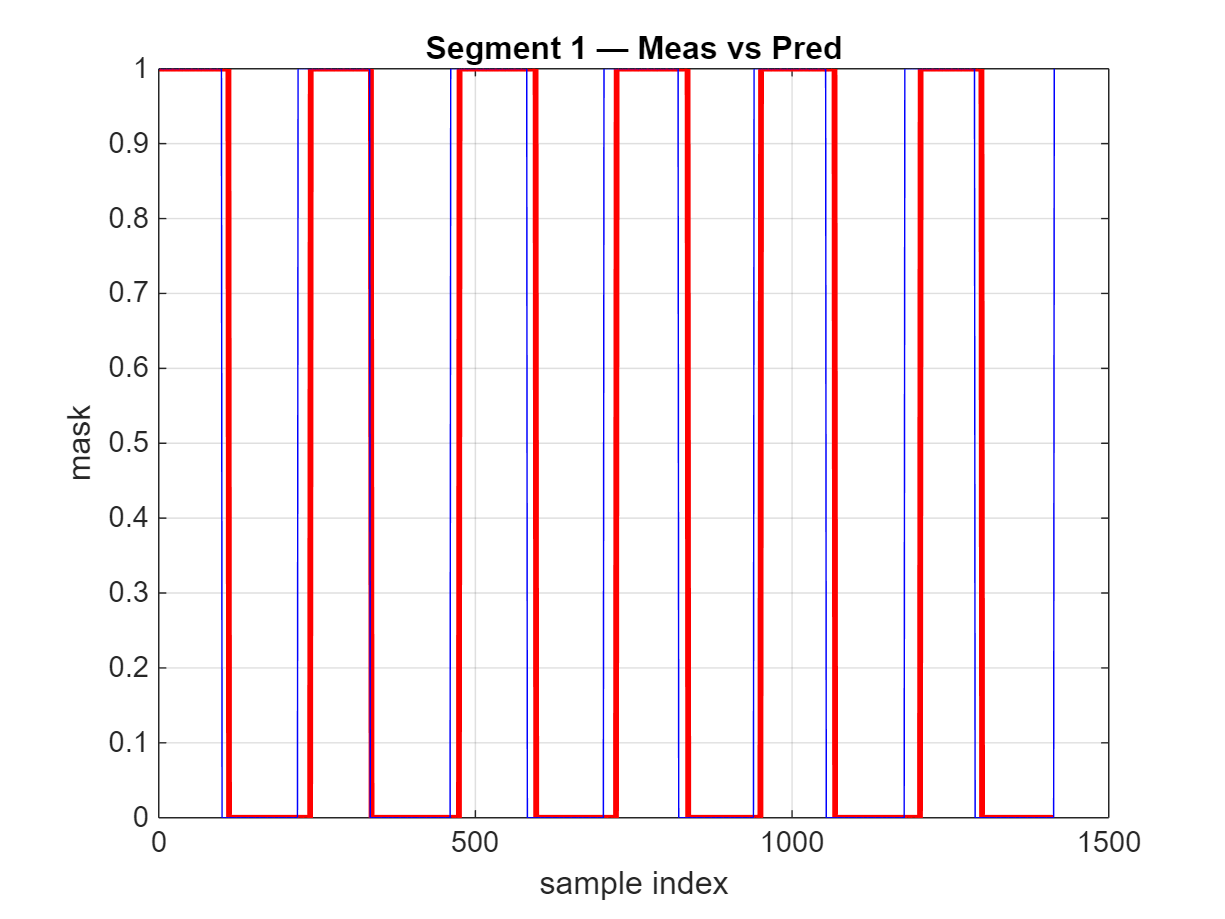

--- Segment 1 ---


Measured ON-time   = 0.2 h


Predicted ON-time  = 0.2 h


Difference         = -24.0 s (-3.5%)



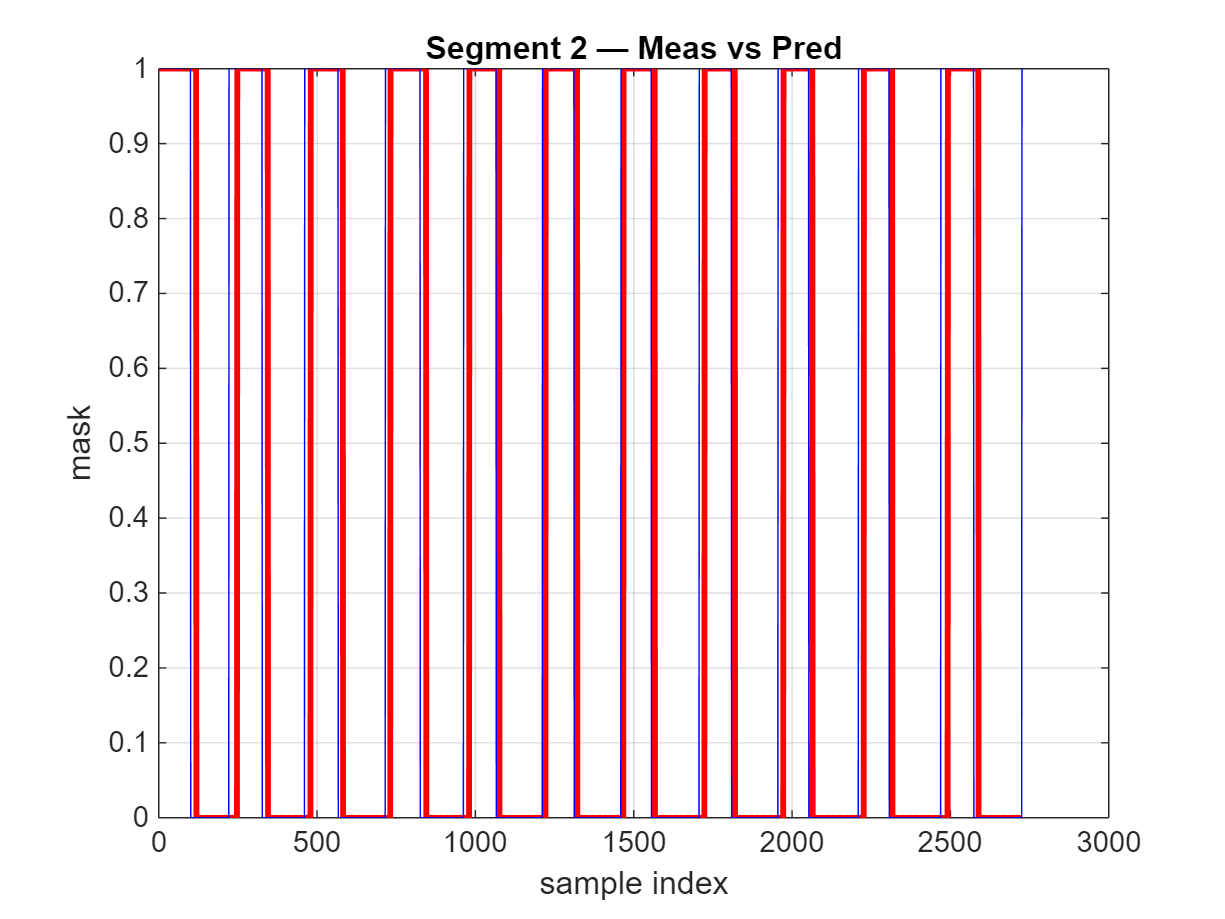

--- Segment 2 ---


Measured ON-time   = 0.3 h


Predicted ON-time  = 0.3 h


Difference         = -22.0 s (-2.0%)



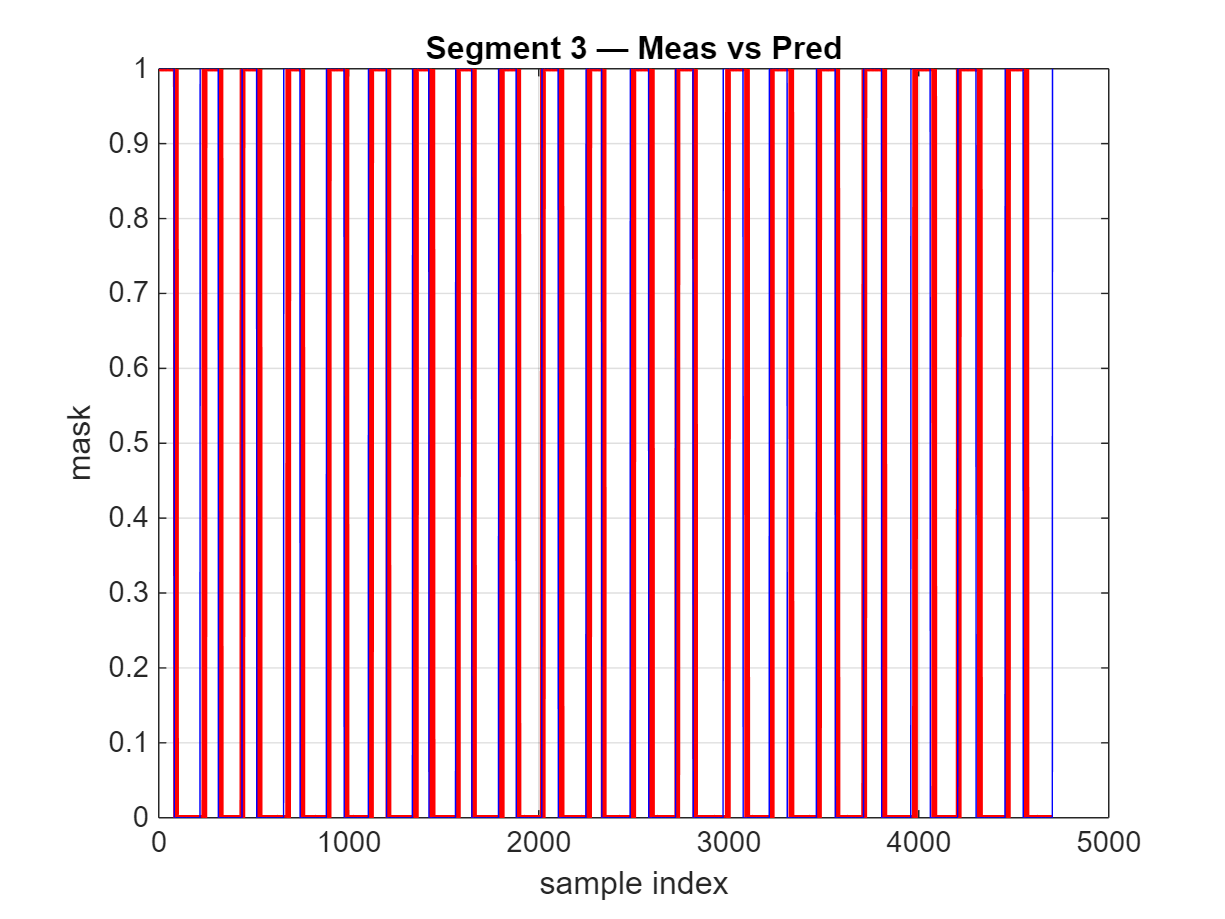

--- Segment 3 ---


Measured ON-time   = 0.5 h


Predicted ON-time  = 0.5 h


Difference         = +23.0 s (1.3%)



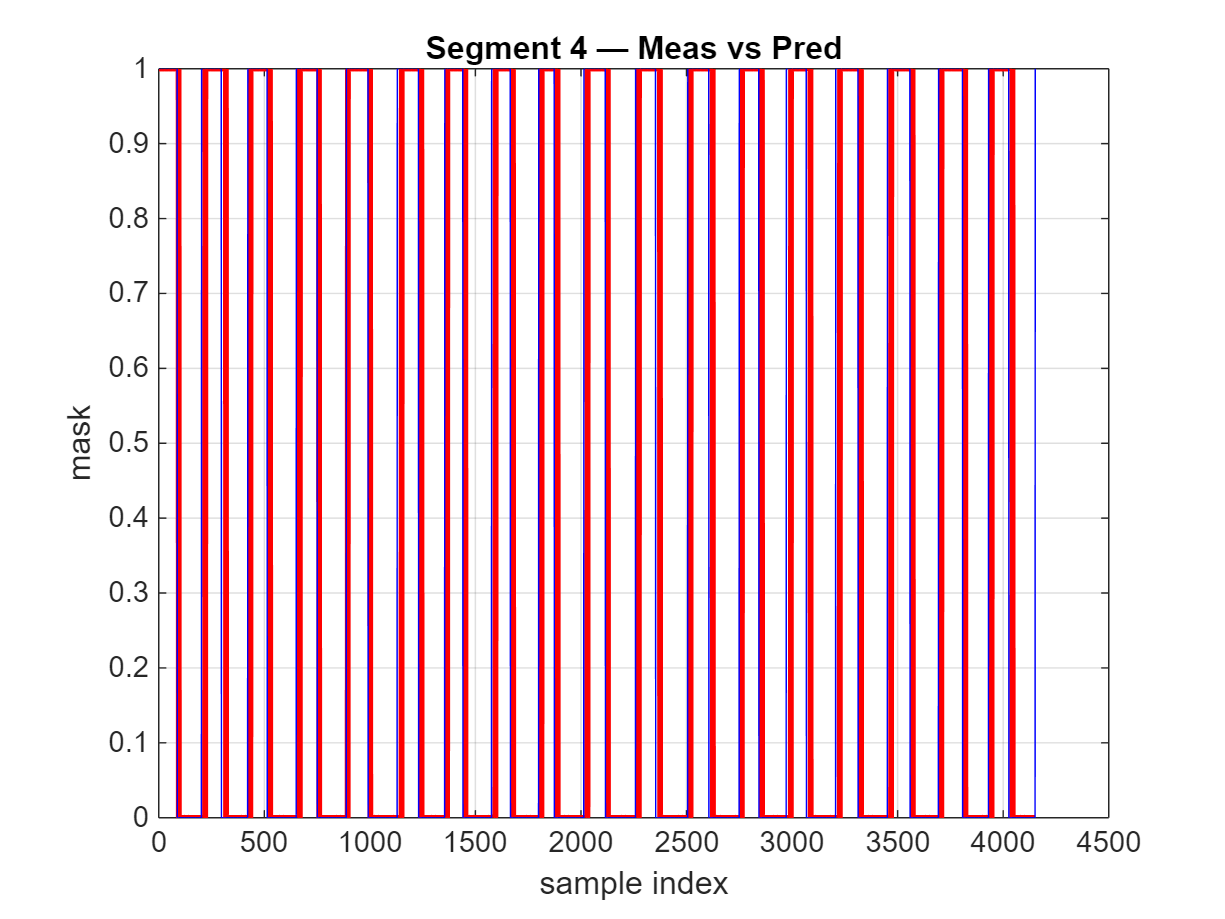

--- Segment 4 ---


Measured ON-time   = 0.5 h


Predicted ON-time  = 0.5 h


Difference         = -10.0 s (-0.6%)



nSets = numel(usableDataIndex);

% Pre‐allocate
mask            = cell(nSets,1);
compressor_idx  = cell(nSets,1);
mask_pred       = cell(nSets,1);
mask_meas       = cell(nSets,1);
stats           = cell(nSets,1);

for i = 1:nSets
    % 1) get this segment’s indices & length
    idx = usableDataIndex{i};
    N   = numel(idx);

    % 2) pull out the numeric vectors for peaks & valleys
    %    (assumes you stored them as cell‐arrays in the previous loop)
    thisLocPeaks   = locs_peaks{i};       % e.g. [45, 98, 153, …]
    thisLocValleys = locs_valleys{i};     % e.g. [72, 120, 185, …]

    % 3) build the 0/1 mask
    mask{i} = peakValleyMask( thisLocPeaks, thisLocValleys, N );

    % 4) grab the compressor signal over the same window
    compressor_idx{i} = compressor_day(idx);

    % 5) define from first peak → end
    startPK = thisLocPeaks(1);
    mp      = mask{i}(startPK:end);
    cm      = compressor_idx{i}(startPK:end);

    % 6) trim measured to match predicted length
    cm = cm(1:numel(mp));

    mask_pred{i} = mp;
    mask_meas{i} = cm;

    % 7) compute ON‐time stats
    stats{i} = compareOnTime(mp, cm);

    % 8) plot
    figure(200+i), clf
    plot(mp, '-r','LineWidth',2), hold on
    plot(cm, '-b'),               hold off
    grid on
    xlabel('sample index')
    ylabel('mask')
    title(sprintf('Segment %d — Meas vs Pred', i))

    % 9) display in Command Window
    fprintf('--- Segment %d ---\n', i)
    fprintf('Measured ON-time   = %.1f h\n', stats{i}.timeOnMeas/3600)
    fprintf('Predicted ON-time  = %.1f h\n', stats{i}.timeOnPred/3600)
    fprintf('Difference         = %+0.1f s (%.1f%%)\n\n', ...
            stats{i}.diffTime, stats{i}.pctError)
end

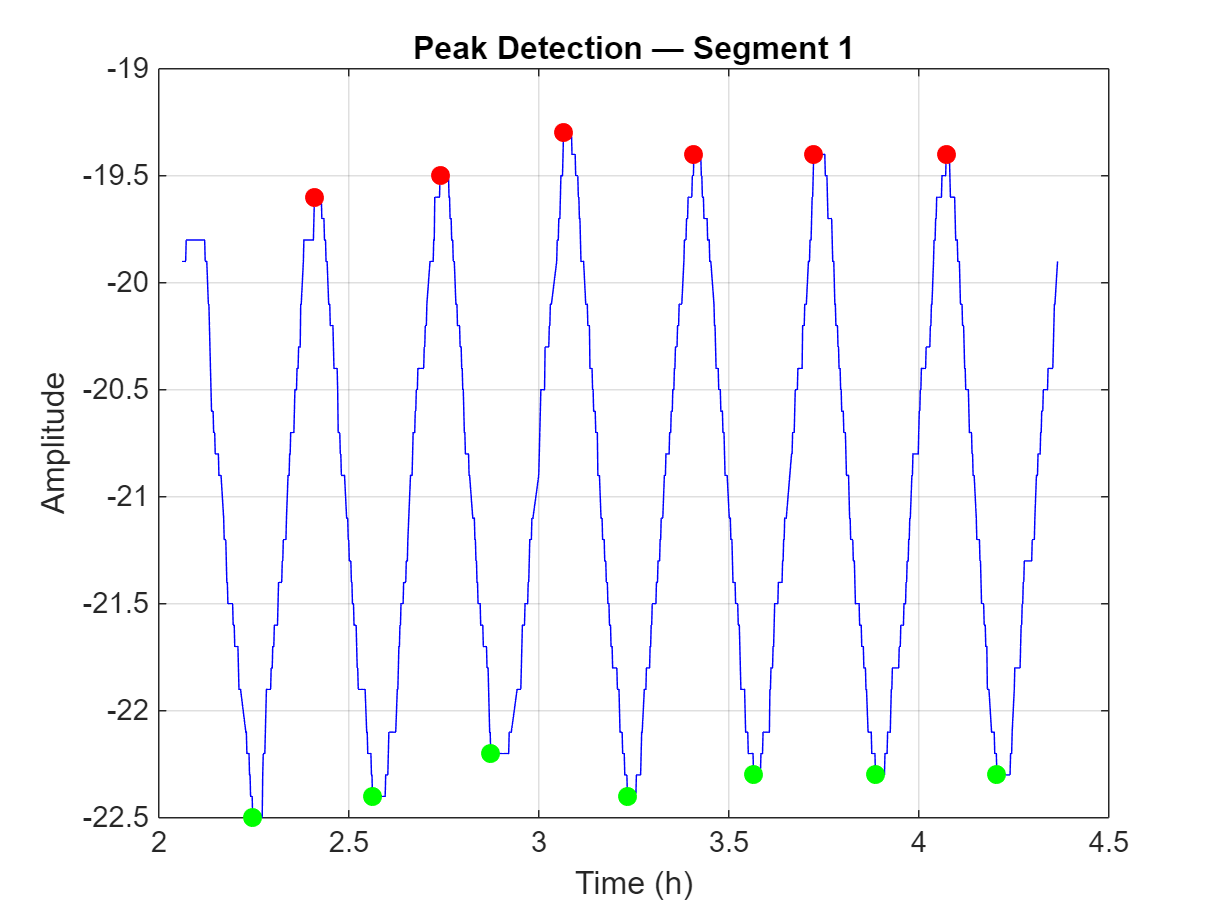

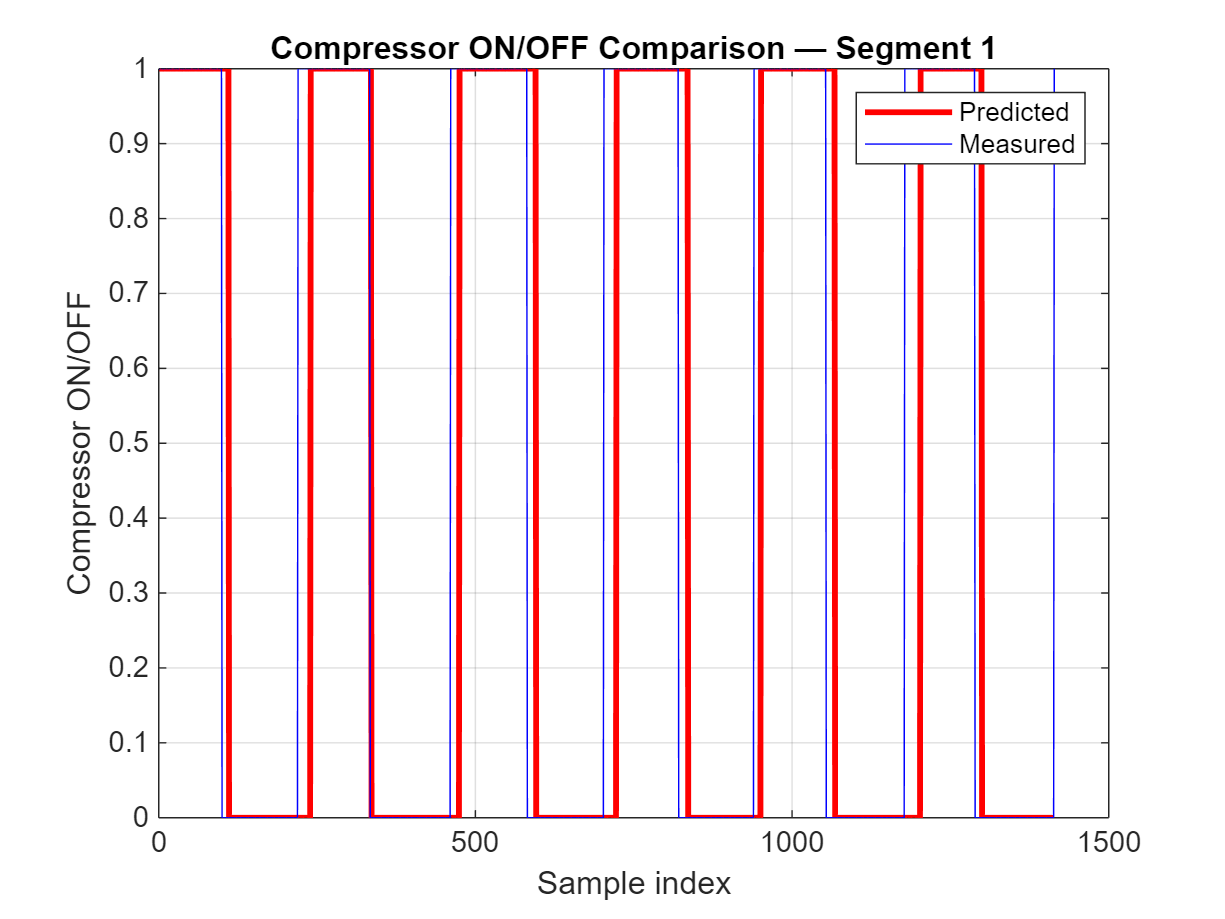

--- Segment 1 ---
Measured ON-time   = 0.2 h
Predicted ON-time  = 0.2 h
Difference         = -24.0 s (-3.5%)



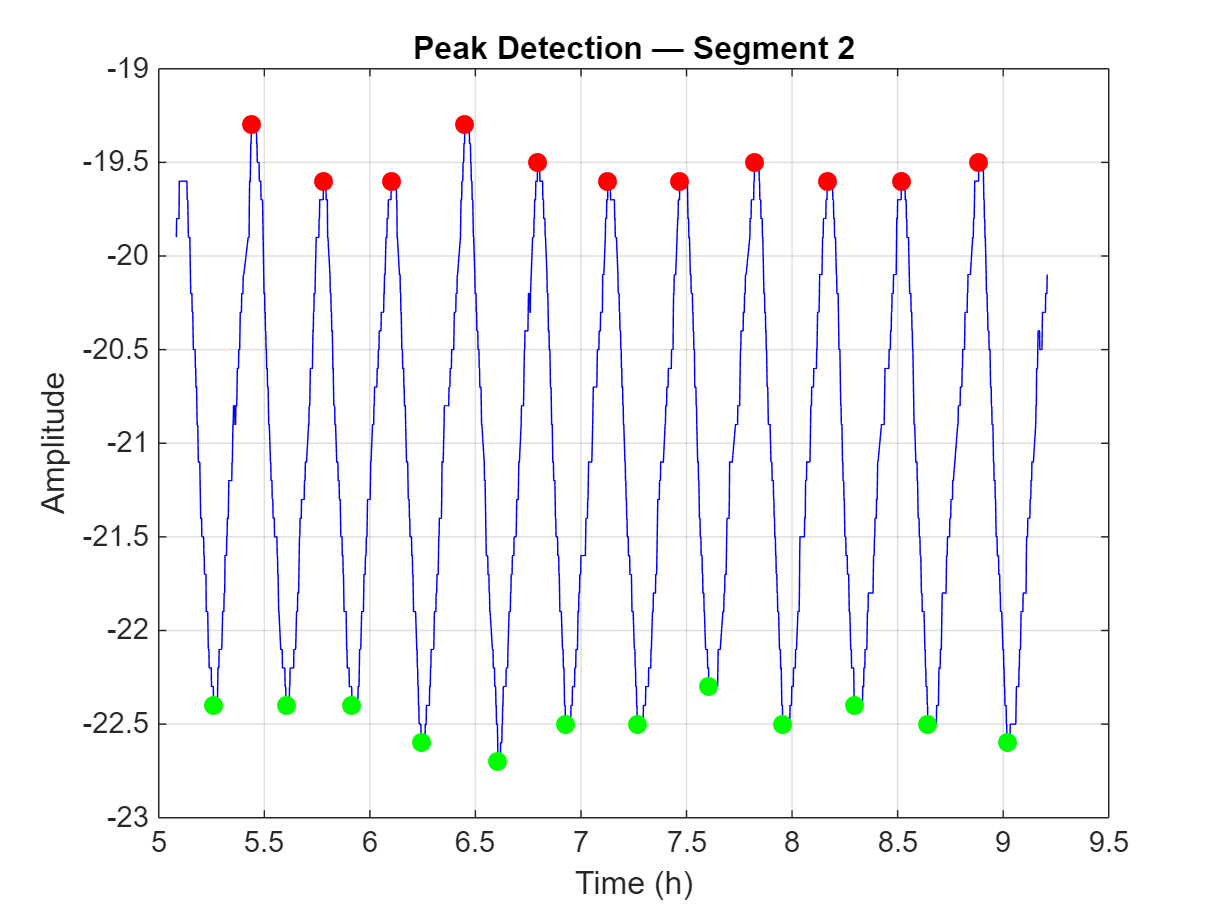

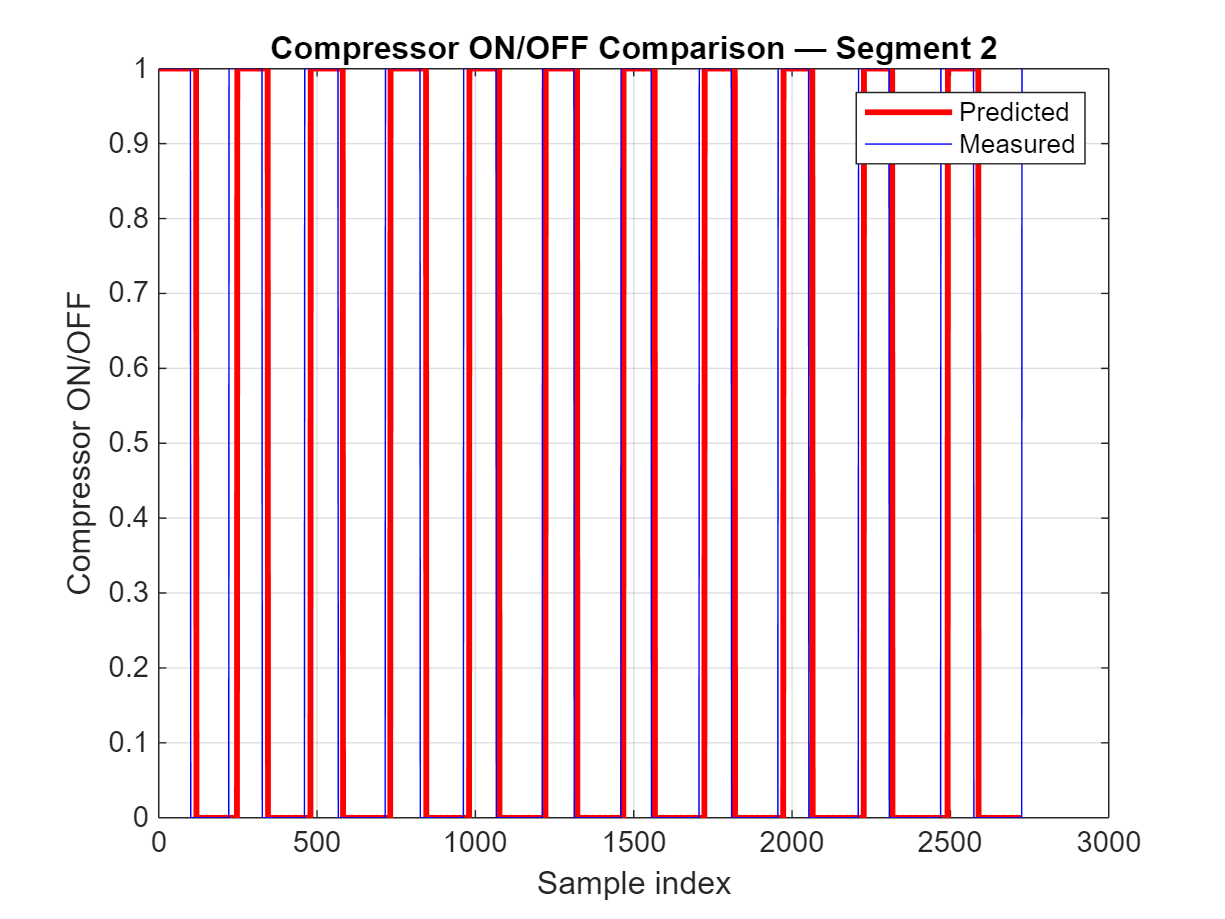

--- Segment 2 ---
Measured ON-time   = 0.3 h
Predicted ON-time  = 0.3 h
Difference         = -22.0 s (-2.0%)



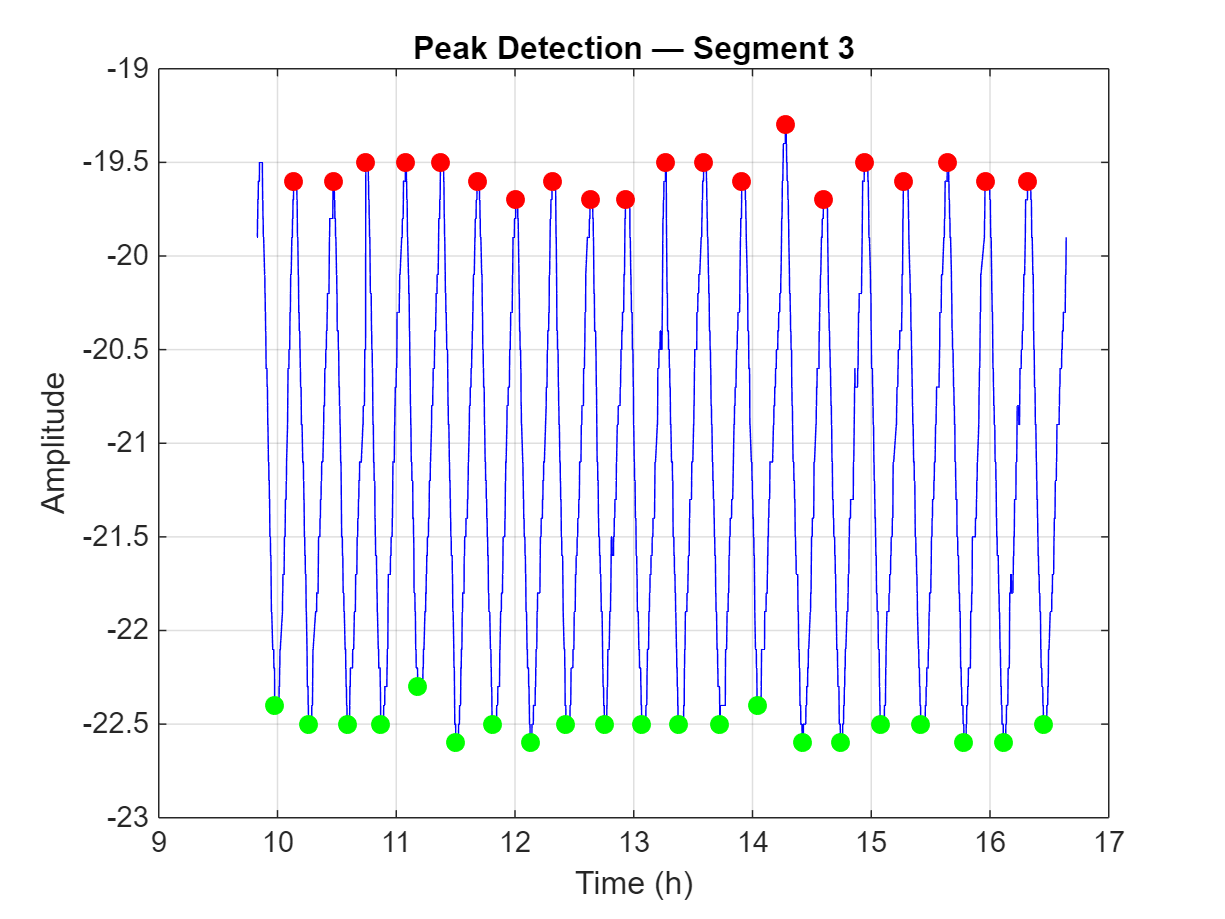

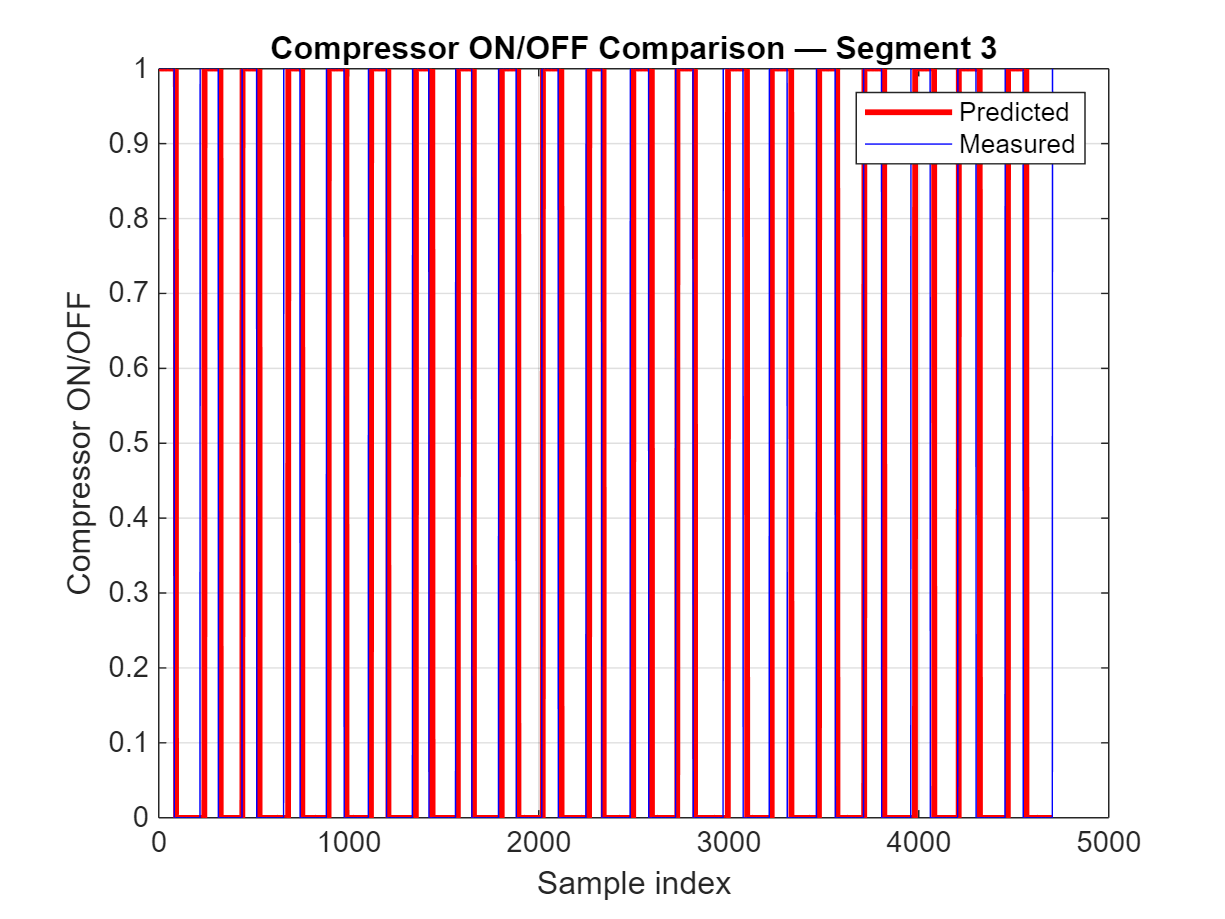

--- Segment 3 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = +23.0 s (1.3%)



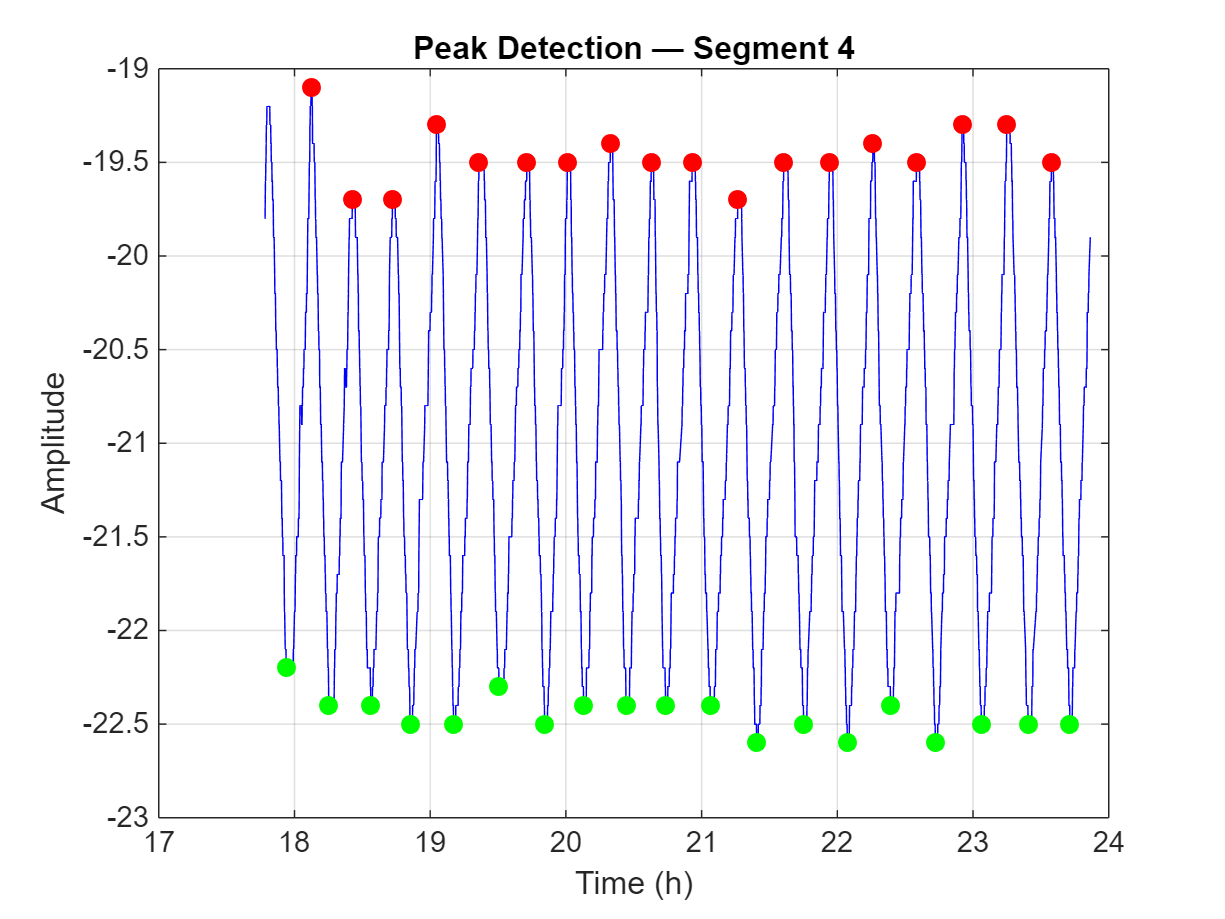

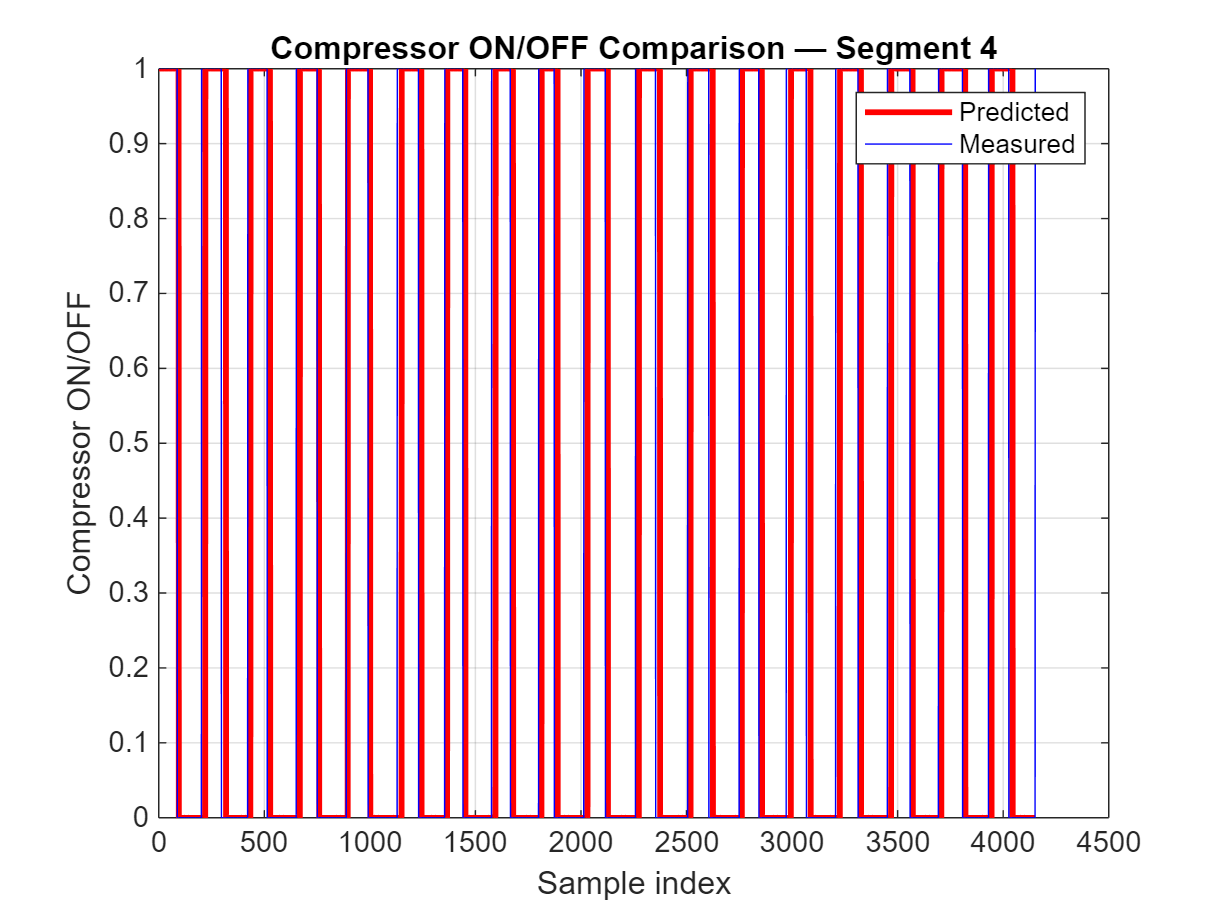

--- Segment 4 ---
Measured ON-time   = 0.5 h
Predicted ON-time  = 0.5 h
Difference         = -10.0 s (-0.6%)



results = analyzeCompressorSegments( ...
    t_day, x_day_interp, compressor_day, usableDataIndex, ...
    'MinPeakProminence', 0.8, ...
    'MinPeakDistance', 0.17, ...
    'PlotResults', true);